# Threshold to Green using L*a*b* color

## Load the image and normalize to 0...1

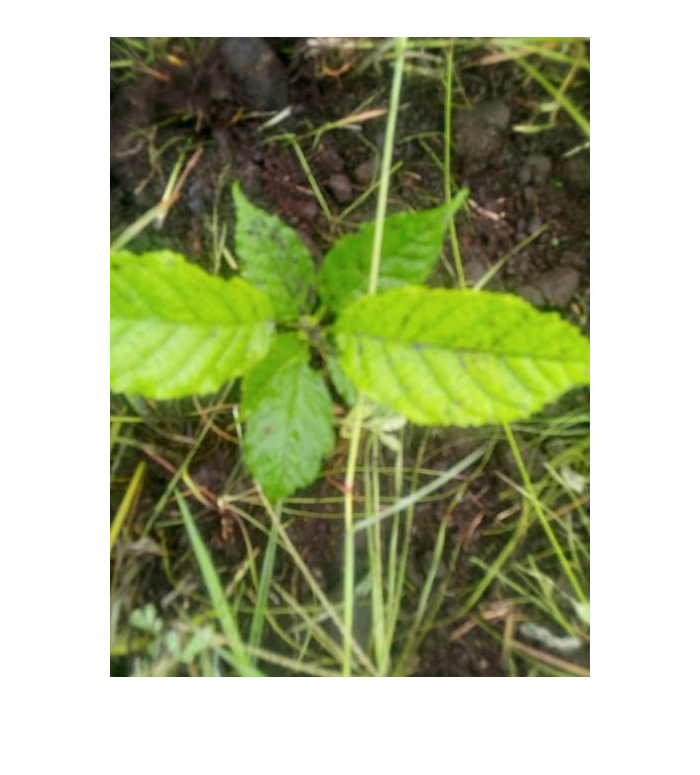

imshow(im1);


labIm1 = rgb2lab(im1);

channelA = labIm1(:,:,2);
 mn = min(min(channelA))

mn = -47.6809

 
channelA = channelA + abs(mn);
channelA = channelA./ max(max(channelA));

Perform Otsu Threshold on a* channel, set the L channel (brightness) to zero

to show only the pixels we want.

 [counts, ~] = imhist(channelA);
 
 cut = otsuthresh(counts)

cut = 0.4353

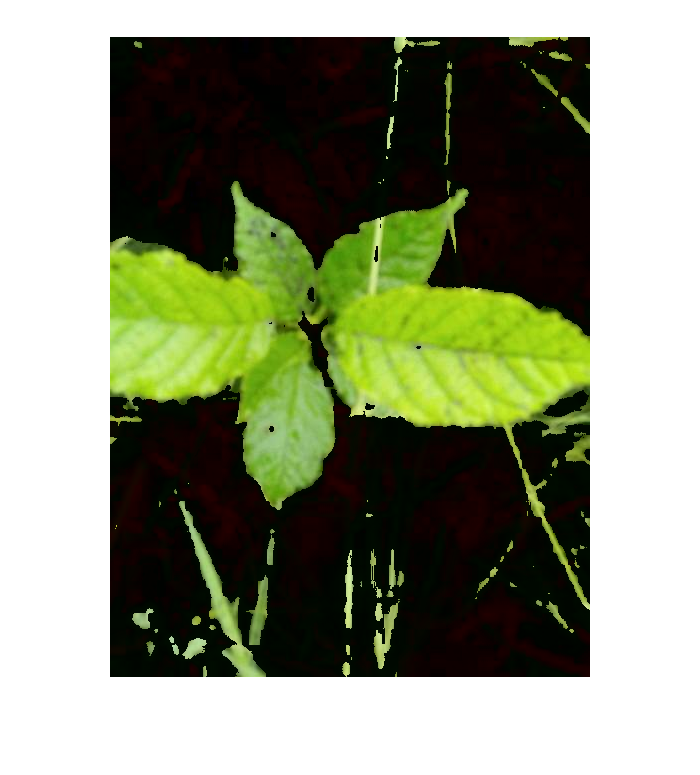

 channelL = labIm1(:,:,1);
  
channelL(channelA > cut) = 0;
labIm1(:,:,1) = channelL;
rgbImage = lab2rgb(labIm1);

imshow(rgbImage);

Repeat for second image.

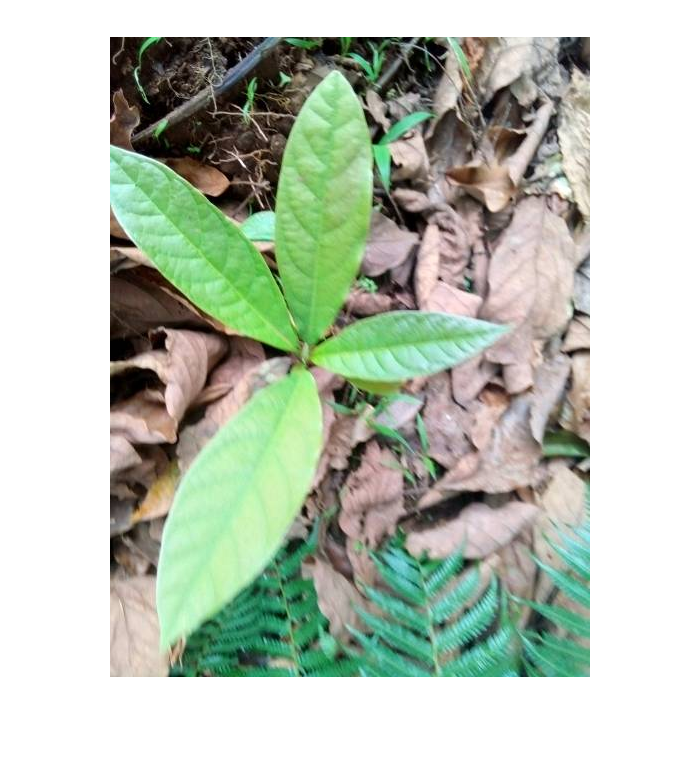

imshow(im2);


labIm1 = rgb2lab(im2);

channelA = labIm1(:,:,2);
 mn = min(min(channelA))

mn = -58.7684

 
channelA = channelA + abs(mn);
channelA = channelA./ max(max(channelA));
 [counts, ~] = imhist(channelA);
 
 cut = otsuthresh(counts)

cut = 0.5373

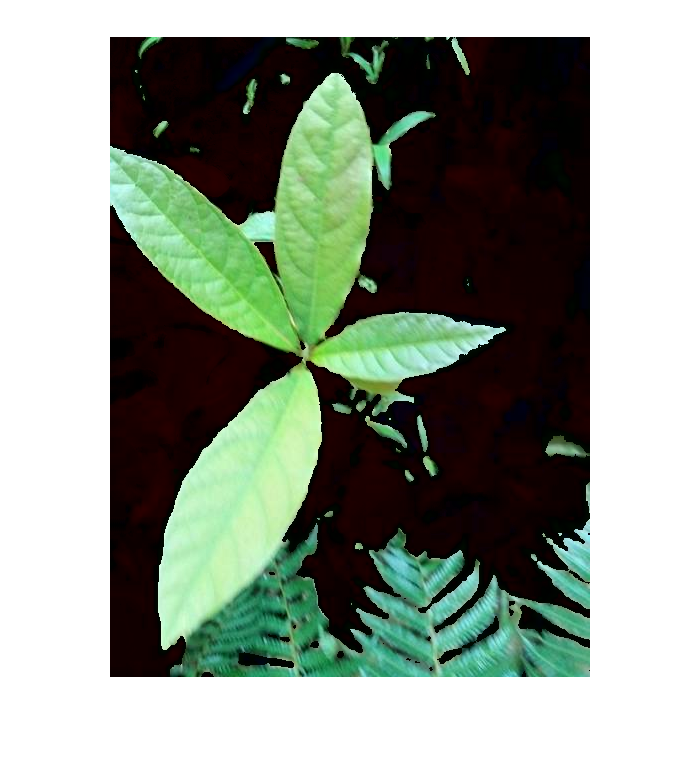

 channelL = labIm1(:,:,1);
  
channelL(channelA > cut) = 0;
labIm1(:,:,1) = channelL;
rgbImage = lab2rgb(labIm1);

imshow(rgbImage);